# Validation with Roach et al. (2018) and Roach et al. (2019)

The purpose of this document is to measure the difference between my runs and those documented in Roach et al. (2018) and Roach et al. (2019).

% Initialisation
clear all
close all
addpath functions
addpath packages/bedmap2_toolbox_v4

filename = '/Users/noahday/Maths1/access-forcing-2010-fixed-ic/history/iceh.2010-09.nc';
%'/Users/noahday/GitHub/CICE-plotting-tools/cases/pancake_tracer/history/iceh.2005-09.nc';
%ncdisp(filename)
% 
grid = 'gx1';
sector = "SH";
[lat, lon, row] = grid_read(grid);

Error using internal.matlab.imagesci.nc/getGroupAndVarid
Could not find variable or group
'ULAT' in file.

Error in internal.matlab.imagesci.nc/read (line 632)
            [gid, varid] = getGroupAndVarid(this, location);

Error in ncread (

case_name = 'pancake_tracer';

NFSD = ncread(filename,"NFSD");
NCAT = ncread(filename,"NCAT");
Nf = length(NFSD);
Nc = length(NCAT);
[floe_binwidth, floe_rad_l, floe_rad_h, floe_area_binwidth] = cice_parameters(NFSD);

### Figure 1. Circumpolar represtative radii in March and September

clear filename
f1 = figure;
sector = "SH";
% Reproduce 

filename.march = "/Users/noahday/Maths1/spectrum_fixed/history/iceh.2005-03.nc";
%filename.march = strcat('cases/',case_name,'/history/iceh.2005-03.nc');
fsdrad_march = data_format_sector(filename.march,"fsdrad",sector);

Error using internal.matlab.imagesci.nc/openToRead
Could not open
/Users/noahday/Maths1/spectrum_fixed/history/iceh.2005-03.nc
for reading.

Error in internal.matlab.imagesci.nc (line 124)
                    this.openToRead();

Error in ncinfo (

filename.sep = "/Users/noahday/Maths1/spectrum_fixed/history/iceh.2005-09.nc";%strcat('cases/',case_name,'/history/iceh.2005-09.nc');
fsdrad_sep = data_format_sector(filename.sep,"fsdrad",sector);
% Apply 1% Mask
SIC = 0.01;
afsd_data(:,:,:) = data_format_sector(filename.march,"afsd","SH");
temp(:,:) = fsd_converter(filename.march,"afsd","aice",afsd_data,"SH");
%temp = data_format_sector(filename.march,"aice",sector);
ice_mask(:,:) = temp > 0.01;
temp(~ice_mask(:,:)) = NaN;
aice(:,:) = temp;
fsdrad_march(~ice_mask(:,:)) = NaN;
afsd_data(:,:,:) = data_format_sector(filename.sep,"afsd","SH");
temp(:,:) = fsd_converter(filename.sep,"afsd","aice",afsd_data,"SH");
ice_mask(:,:) = temp > 0.01;
temp(~ice_mask(:,:)) = NaN;
aice(:,:) = temp;
fsdrad_sep(~ice_mask(:,:)) = NaN;

max_rad = 3000;
subplot(2,2,1)
[w, a, ~] = map_plot(fsdrad_march,"fsdrad","SHplainnocbar"); 
cmocean('deep',10)
caxis([0,600]);
subplot(2,2,3)
[w, a, ~] = map_plot(fsdrad_sep,"fsdrad","SHplain"); 
cmocean('deep',10)
a.Location = 'southoutside';
a.Label.String = 'Representative radius [m]';
a.Ticks = [0,200,400,600];
caxis([0,600]);

subplot(2,2,[2,4])
imshow(imread("observations/roach_2018/fig1.png"))
clear temp w output_data fsdrad_march fsdrad_sep aice icemask max_rad filename

### Figure 2. Number distribution and number distribution tendencies per FSD process

clear filename nfsd_dist
filename.march = "/Users/noahday/Maths1/spectrum_fixed/history/iceh.2005-03.nc";
filename.sep = "/Users/noahday/Maths1/spectrum_fixed/history/iceh.2005-09.nc";
NFSD = ncread(filename.march,"NFSD");
[floe_binwidth] = cice_parameters(NFSD);
sector = "SH";

afsdn_data = data_format_sector(filename.march,"afsdn",sector);
n_fsd.march = fsd_converter(filename.march,"afsdn","n_fsd",afsdn_data,sector);
nfsd_dist.march = integrate_afsd_hemi(lat,floe_binwidth',n_fsd.march);

afsdn_data = data_format_sector(filename.sep,"afsdn",sector);
n_fsd.sep = fsd_converter(filename.sep,"afsdn","n_fsd",afsdn_data,sector);
nfsd_dist.sep = integrate_afsd_hemi(lat,floe_binwidth',n_fsd.sep);

afsd_data = data_format_sector(filename.sep,"afsd",sector);
n_fsd.sep = fsd_converter(filename.sep,"afsd","n_fsd",afsd_data,sector);
nfsd_dist.sep2 = integrate_afsd_hemi(lat,floe_binwidth',n_fsd.sep);

dafsd_latm_data = data_format_sector(filename.march,"dafsd_latm",sector);
n_fsd.march_latm = fsd_converter(filename.march,"afsd","n_fsd",dafsd_latm_data,sector);
nfsd_dist.march_latm = integrate_afsd_hemi(lat,floe_binwidth',n_fsd.march_latm);

dafsd_latg_data = data_format_sector(filename.march,"dafsd_latg",sector);
n_fsd.march_latg = fsd_converter(filename.march,"afsd","n_fsd",dafsd_latg_data,sector);
nfsd_dist.march_latg = integrate_afsd_hemi(lat,floe_binwidth',n_fsd.march_latg);

dafsd_newi_data = data_format_sector(filename.march,"dafsd_newi",sector);
n_fsd.march_newi = fsd_converter(filename.march,"afsd","n_fsd",dafsd_newi_data,sector);
nfsd_dist.march_newi = integrate_afsd_hemi(lat,floe_binwidth',n_fsd.march_newi);

dafsd_weld_data = data_format_sector(filename.march,"dafsd_weld",sector);
n_fsd.march_weld = fsd_converter(filename.march,"afsd","n_fsd",dafsd_weld_data,sector);
nfsd_dist.march_weld = integrate_afsd_hemi(lat,floe_binwidth',n_fsd.march_weld);

dafsd_wave_data = data_format_sector(filename.march,"dafsd_wave",sector);
n_fsd.march_wave = fsd_converter(filename.march,"afsd","n_fsd",dafsd_wave_data,sector);
nfsd_dist.march_wave = integrate_afsd_hemi(lat,floe_binwidth',n_fsd.march_wave);

%filename_roach18 = "/Volumes/NoahDay5TB/roach_2018/u-ai251i.1m.0046-0065.areal_fsd_m.nc";
%[lat, lon, row] = grid_read(grid);
%NFSD_roach18 = [5.31030845642089844 14.2865858078002930 29.0576686859130859 52.4122123718261719 87.8691406250000000 139.518463134765625 211.635757446289062 308.037261962890625 431.203063964843750 581.277221679687500 755.141052246093750 945.81280517578125];
%lat_roach18 = ncread(filename_roach18,"TLAT");lon_roach18 = ncread(filename_roach18,"TLON");
%afsd_t = ncread(filename_roach18,"areal_fsd_m");% time is in months take the last september
%afsd_roach18(:,:,:) = afsd_t(:,:,:,237); 
%floe_binwidth_roach18 = cice_parameters(NFSD_roach18);
%n_fsd.roach_sep = fsd_converter(filename_roach18,"afsd","n_fsd",afsd_roach18,sector);
%nfsd_dist.sep = integrate_afsd_hemi(lat,floe_binwidth_roach18',n_fsd.roach_sep);




close all
f2 = figure;
subplot(4,2,1)
loglog(NFSD,nfsd_dist.march)
ylim([10^(-9), 10^5])
xlim([0,10^3])
ylabel('Number distribution [km$^{-2}$]')
grid on

subplot(4,2,3)
loglog(NFSD,nfsd_dist.sep)
hold on
loglog(NFSD,nfsd_dist.sep2)
hold off
ylim([10^(-9), 10^5])
xlim([0,10^3])
ylabel('Number distribution [km$^{-2}$]')
xlabel('Floe radius [m]')
grid on



%ylim([-10^(3), 10^3])
xlim([0,10^3])
ylabel('Number distribution tendency [km$^{-2}$ day$^{-1}$]')
xlabel('Floe radius [m]')
grid on

subplot(4,2,[5,8])
imshow(imread("observations/roach_2018/fig2.png"))


figure
%subplot(4,2,2)
plot(NFSD,nfsd_dist.march_latm )
hold on
plot(NFSD,nfsd_dist.march_latg )
plot(NFSD,nfsd_dist.march_newi )
plot(NFSD,nfsd_dist.march_weld )
plot(NFSD,nfsd_dist.march_wave )
hold off
xlim([1,10^3])
xlabel('Floe radius [m]')
symlog(gca,'xy')
legend('Latm','Latg','Newi','Weld','Wave')

### Figure 3. Change in representative radius per day per FSD process

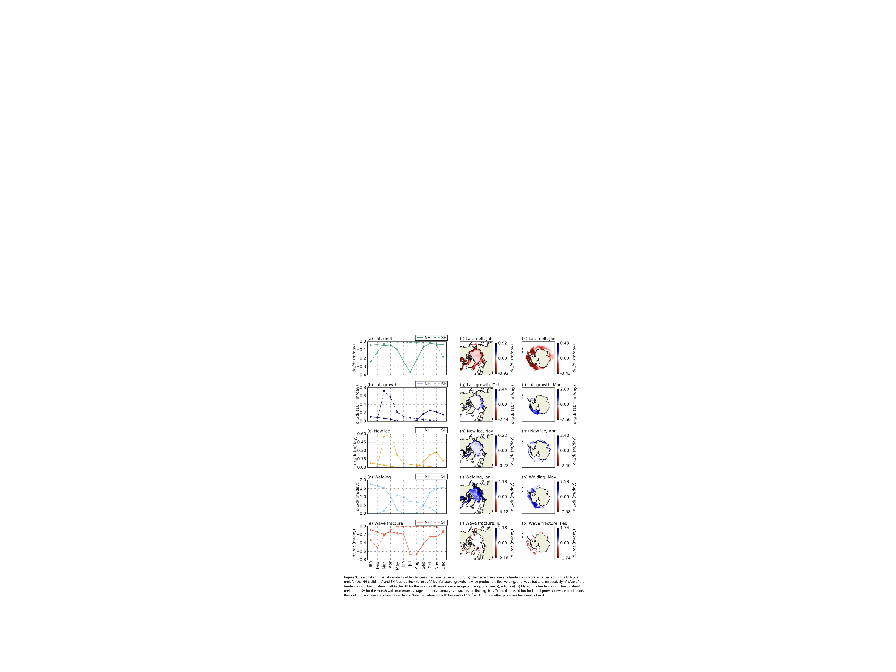

f3 = figure;
subplot(10,2,[11,20])
imshow(imread("observations/roach_2018/fig3.png"))

### Model output: NEMO-CICE with an emergent sea ice floe size distribution (https://zenodo.org/record/1193930#.Ysyyly8Rojc)

#### Areal FSD (u-ai251i.1m.0046-0065.areal_fsd_m.nc)

% Mapping the areal FSD data from Roach et al. 2018
filename = "/Volumes/NoahDay5TB/roach_2018/u-ai251i.1m.0046-0065.areal_fsd_m.nc";
sector = "SH";
afsd_t = ncread(filename,"areal_fsd_m");
% time is in months
% take the last september
afsd_roach(:,:,:) = afsd_t(:,:,:,237); 
NFSD12 = NFSD(1:12);
lat_roach18 = ncread(filename,"TLAT");
lon_roach18 = ncread(filename,"TLON");
filename = "/Volumes/NoahDay5TB/roach_2019/cice_FSDv2_LR_2000-2014.nc";
afsd_t = ncread(filename,"areal_fsd");
afsd_roach19(:,:,:) = afsd_t(:,:,:,177); % Last September
NFSD_roach18 = [5.31030845642089844 14.2865858078002930 29.0576686859130859 52.4122123718261719 87.8691406250000000 139.518463134765625 211.635757446289062 308.037261962890625 431.203063964843750 581.277221679687500 755.141052246093750 945.81280517578125];
[floe_binwidth_r18, floe_rad_l_r18, floe_rad_h_r18, floe_area_binwidth_r18] = cice_parameters(NFSD_roach18)

floe_binwidth_r18 =    10.4876    7.4649   22.0772   24.6319   46.2820   57.0166   87.2179  105.5851  140.7465  159.4018  188.3259  193.0176


floe_rad_l_r18 =     0.0665   10.5541   18.0191   40.0963   64.7281  111.0101  168.0268  255.2447  360.8298  501.5763  660.9781  849.3040


floe_rad_h_r18 = 1.0e+03 *

    0.0106    0.0180    0.0401    0.0647    0.1110    0.1680    0.2552    0.3608    0.5016    0.6610    0.8493    1.0423


floe_area_binwidth_r18 = 1.0e+05 *

    0.0029    0.0056    0.0339    0.0682    0.2147    0.4200    0.9746    1.7173    3.2044    4.8923    7.5088    9.6391


NFSD_roach19 = ncread(filename,"NFSD");
NFSD12 = NFSD(1:12);
lat_roach19 = ncread(filename,"TLAT");
lon_roach19 = ncread(filename,"TLON");

figure
[lat, lon, row] = grid_read(grid);
%filename = strcat('cases/',case_name,'/history/iceh.2005-09.nc');
filename = "/Users/noahday/Maths1/spectrum_fixed/history/iceh.2005-09.nc";
afsd = data_format_sector(filename,"afsd",sector);

for i = 1:12
   afsd12(:,:,i) = afsd(:,:,i).*NFSD(i);
end
for nf = 1:4
    afsd12(:,:,12) = afsd12(:,:,12)+ afsd(:,:,12+nf).*NFSD(nf);
end

Index in position 3
exceeds array bounds.
Index must not exceed
12.

for i = 1:12
    subplot(3,12,i)
    w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat_roach18),double(lon_roach18),afsd_roach(:,:,i).*NFSD_roach18(i));
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
            %if i == 12
                a = colorbar;
            %end
            %caxis([0,0.3]);

    subplot(3,12,12 + i)
    w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat),double(lon),afsd12(:,:,i).*NFSD12(i));
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
            %if i == 12
                a = colorbar;
            %end
            %caxis([0,0.3]);
    
    % FSD-WAVEv2
    subplot(3,12,24 + i)
    w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat_roach19),double(lon_roach19),afsd_roach19(:,:,i));
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
            %if i == 12
                a = colorbar;
            %end
            %caxis([0,0.3]);
end

% Calculate the circumpolar FSDs for comparison
% Method:
% 1. Take AFSD and apply a 1% ice mask
% 2. Sum over all cells 
% 3. Plot the distributions in terms of 1/m
clear temp fsd_dist
filename_roach18 = "/Volumes/NoahDay5TB/roach_2018/u-ai251i.1m.0046-0065.areal_fsd_m.nc";
filename_roach19 = "/Volumes/NoahDay5TB/roach_2019/cice_FSDv2_LR_2000-2014.nc";
%filename = "/Users/noahday/Maths1/iceh.2005-09.nc";  % Wave forcing on WIM on
filename = strcat('cases/',case_name,'/history/iceh.2005-09.nc');
%filename2 = strcat('cases/',case_name,'/history/iceh.2005-09.nc');
filename2 = "/Users/noahday/maths1/spectrum_fixed/history/iceh.2005-09.nc";%"/Users/noahday/GitHub/CICE-plotting-tools/cases/monthnoforce/history/iceh.2005-09.nc"; % Wave forcing off
filename3 = "/Users/noahday/GitHub/CICE-plotting-tools/cases/wimoff/history/iceh.2005-09-01.nc"; % Wave forcing on WIM off

[lat, lon, row] = grid_read(grid);
NFSD_roach18 = [5.31030845642089844 14.2865858078002930 29.0576686859130859 52.4122123718261719 87.8691406250000000 139.518463134765625 211.635757446289062 308.037261962890625 431.203063964843750 581.277221679687500 755.141052246093750 945.81280517578125];
NFSD_roach19 = ncread(filename_roach19,"NFSD");

NFSD12 = NFSD(1:12);
lat_roach18 = ncread(filename_roach18,"TLAT");lon_roach18 = ncread(filename_roach18,"TLON");
lat_roach19 = ncread(filename_roach19,"TLAT");lon_roach19 = ncread(filename_roach19,"TLON");

afsd_t = ncread(filename_roach18,"areal_fsd_m");% time is in months take the last september
afsd_roach18(:,:,:) = afsd_t(:,:,:,237); 
afsd_t = ncread(filename_roach19,"areal_fsd");
afsd_roach19(:,:,:) = afsd_t(:,:,:,177); % Last September

afsd = data_format_sector(filename,"afsd","SH");
afsd2 = data_format_sector(filename2,"afsd","SH");
afsd3 = data_format_sector(filename3,"afsd","SH");


[floe_binwidth18] = cice_parameters(NFSD_roach18);

Unrecognized function or variable
'NFSD_roach18'.

fsd_dist.roach18 = integrate_afsd_hemi(lat_roach18,floe_binwidth18',afsd_roach18);
[floe_binwidth19] = cice_parameters(NFSD_roach19);
fsd_dist.roach19 = integrate_afsd_hemi(lat_roach19,floe_binwidth19',afsd_roach19);
[floe_binwidth] = cice_parameters(NFSD);
NFSD = ncread(filename,"NFSD");

[floe_binwidth] = cice_parameters(NFSD);
fsd_dist.cice = integrate_afsd_hemi(lat,floe_binwidth',afsd);


NFSD2 = ncread(filename2,"NFSD");
[floe_binwidth2] = cice_parameters(NFSD2);
fsd_dist.cice2 = integrate_afsd_hemi(lat,floe_binwidth2',afsd2);
NFSD3 = ncread(filename3,"NFSD");
[floe_binwidth3] = cice_parameters(NFSD3);
fsd_dist.cice3 = integrate_afsd_hemi(lat,floe_binwidth3',afsd3);

disp("Data formatting completed.")
clear afsd_roach18 afsd_roach19 afsd afsd2 afsd3 afsd_t

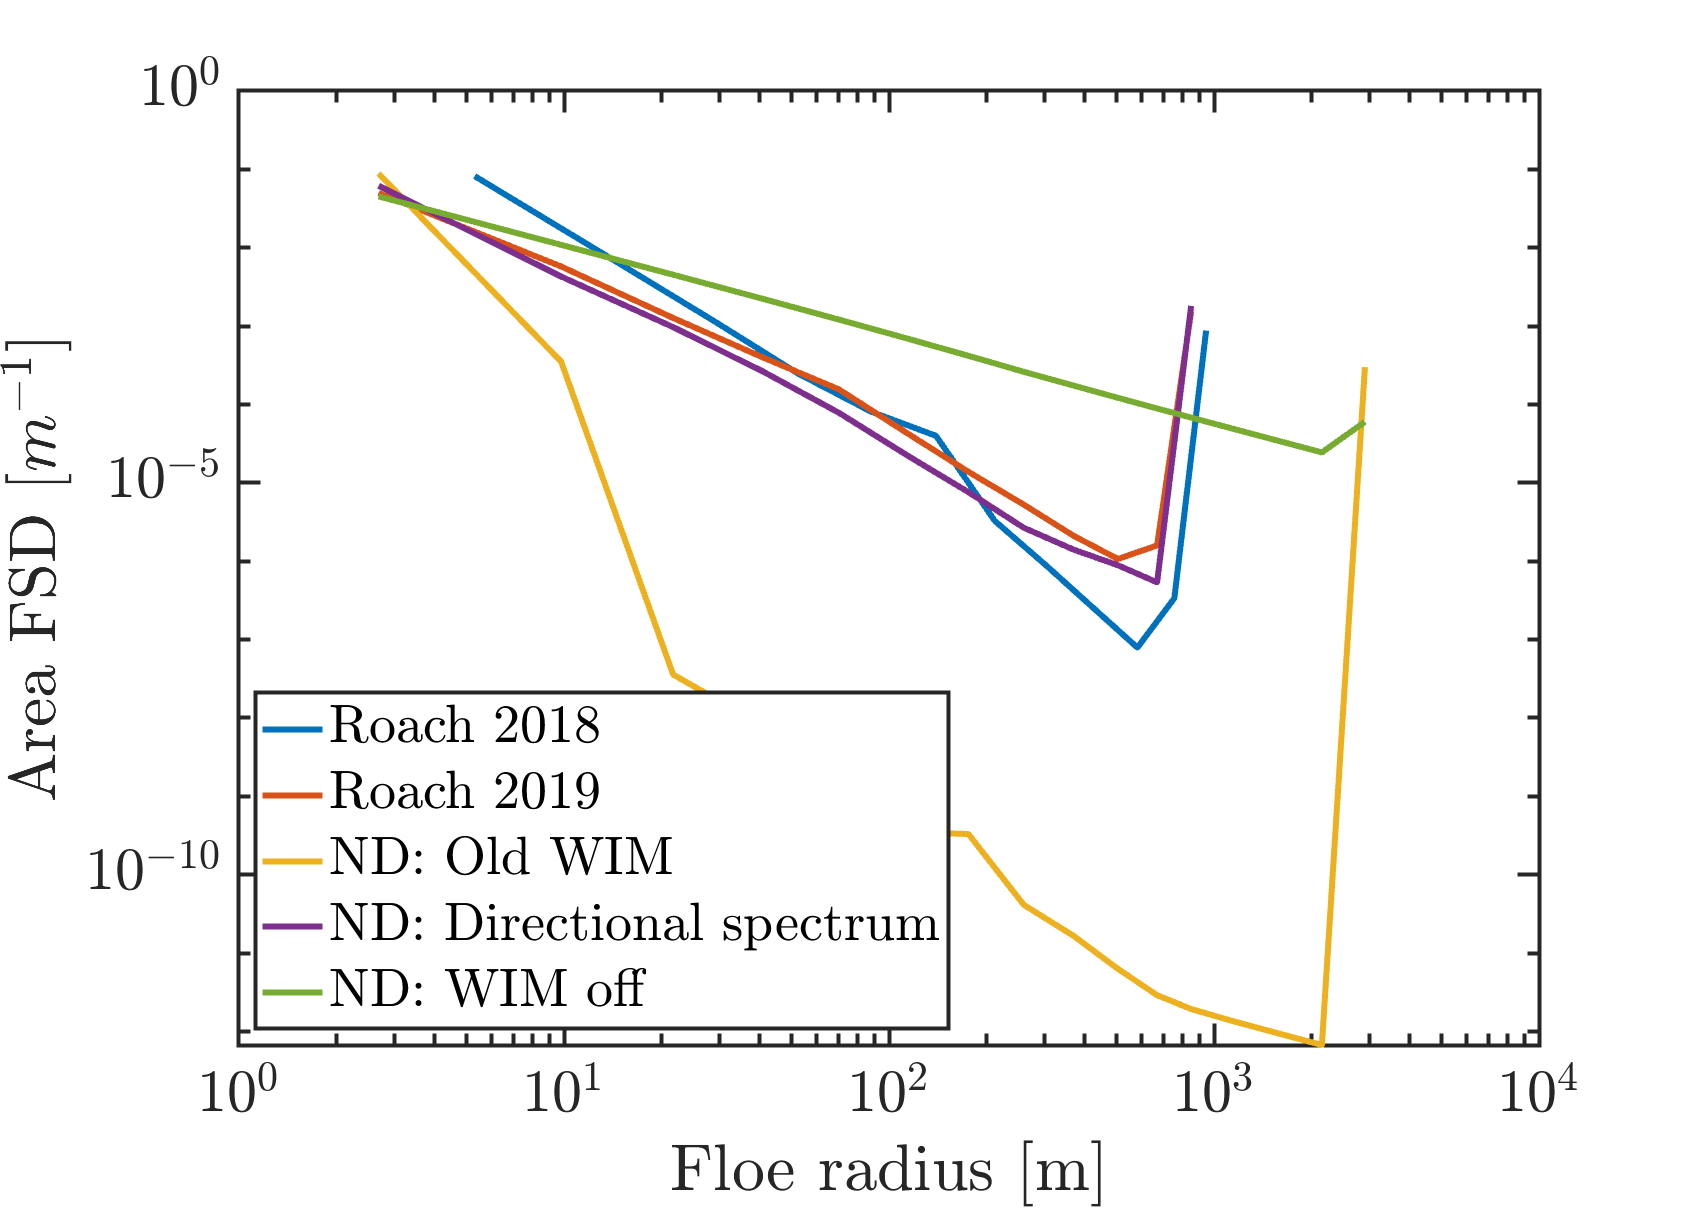

conFigure(30)
f1 = figure;
loglog(NFSD_roach18,fsd_dist.roach18,'LineWidth',3)
hold on
loglog(NFSD_roach19,fsd_dist.roach19,'LineWidth',3)
loglog(NFSD,fsd_dist.cice,'LineWidth',3)
loglog(NFSD2,fsd_dist.cice2,'LineWidth',3)
loglog(NFSD3,fsd_dist.cice3,'LineWidth',3)
xlabel('Floe radius [m]')
ylabel('Area FSD [$m^{-1}$]')
legend('Roach 2018','Roach 2019','ND: Old WIM','ND: Directional spectrum','ND: WIM off','Location','southwest')
hold off

exportgraphics(f1,'fsdcomp.pdf','ContentType','vector')

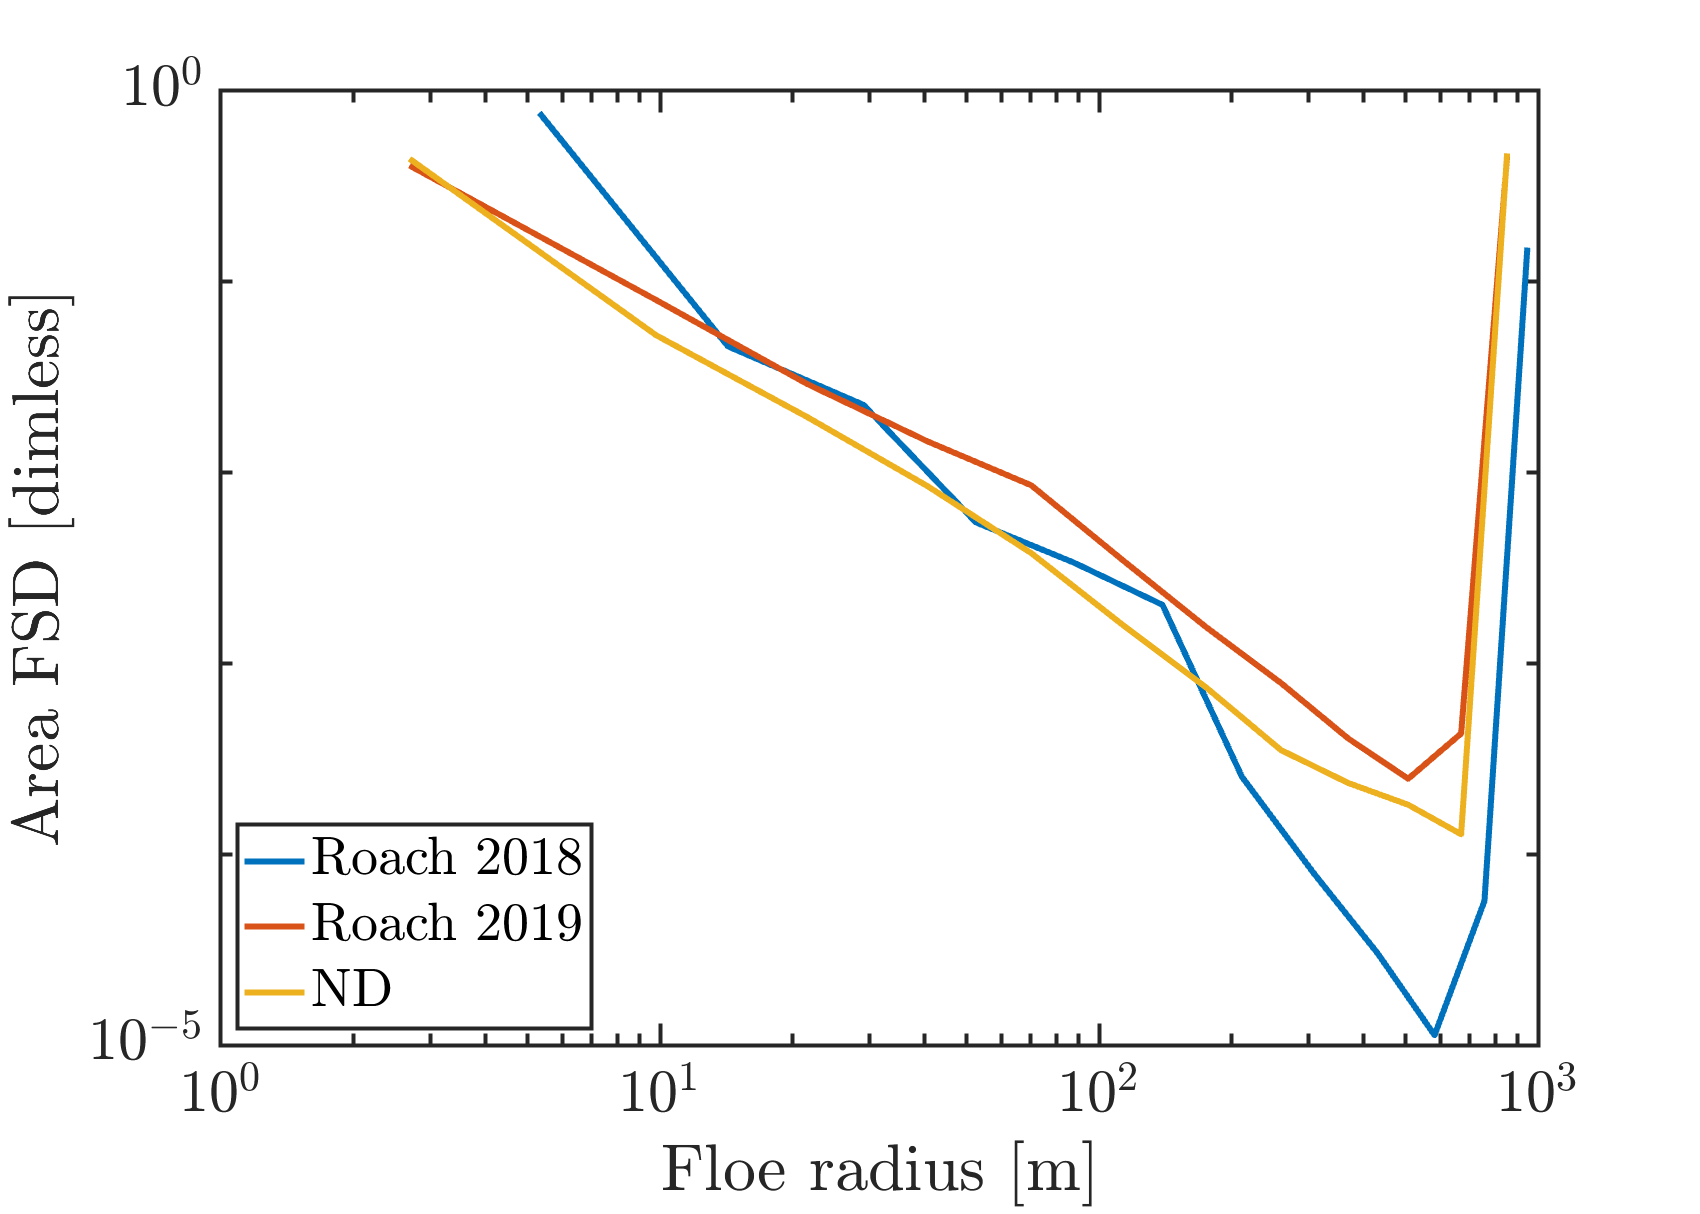


f2 = figure;
loglog(NFSD_roach18,fsd_dist.roach18.*floe_binwidth18/sum(fsd_dist.roach18.*floe_binwidth18),'LineWidth',3)
hold on
loglog(NFSD_roach19,fsd_dist.roach19.*floe_binwidth19/sum(fsd_dist.roach19.*floe_binwidth19),'LineWidth',3)
loglog(NFSD2,fsd_dist.cice2.*floe_binwidth2/sum(fsd_dist.cice2.*floe_binwidth2),'LineWidth',3)
xlabel('Floe radius [m]')
ylabel('Area FSD [dimless]')
legend('Roach 2018','Roach 2019','ND','Location','southwest')
exportgraphics(f2,'fsdcompdimless.pdf','ContentType','vector')

% aice_bar = [mean(aice_roach18(ice_mask_roach18)),mean(aice_roach19(ice_mask_roach19)),mean(aice(ice_mask))];
% f3 = figure;
% bar(aice_bar)

#### Change in FSD due to waves

filename_roach18_wave = "/Volumes/NoahDay5TB/roach_2018/u-ai251i.1m.0046-0065.dafsdwave_m.nc";
%ncdisp(filename_roach18_wave)
NFSD_roach18 = [5.31030845642089844 14.2865858078002930 29.0576686859130859 52.4122123718261719 87.8691406250000000 139.518463134765625 211.635757446289062 308.037261962890625 431.203063964843750 581.277221679687500 755.141052246093750 945.81280517578125];
lat_roach18 = ncread(filename_roach18_wave,"TLAT");lon_roach18 = ncread(filename_roach18_wave,"TLON");
dafsd_t = ncread(filename_roach18_wave,"dafsdwave_m");% time is in months take the last september
dafsd_roach18(:,:,:) = dafsd_t(:,:,:,237); 
%[test,afsd,aice,dafsd] = integrate_afsd_hemi(lat_roach18,floe_binwidth18(1:12)',dafsd_roach18); % dafsd_wave.roach18
[data_out] = dfsdrad(lat_roach18,NFSD_roach18',floe_binwidth18(1:12),dafsd_roach18);

Unrecognized function
or variable
'floe_binwidth18'.



filename = "/Users/noahday/Maths1/spectrum_fixed/history/iceh.2005-09.nc";%strcat('cases/',case_name,'/history/iceh.2005-09.nc');
dafsd_wave = data_format_sector(filename,"dafsd_wave","SH");
%dafsd_wave.ndwave = integrate_afsd_hemi(lat,NFSD,dafsd_wave);
[dafsd_wave_ra] = dfsdrad(lat,NFSD2,floe_binwidth2,dafsd_wave);

figure;   
subplot(1,2,1)
title('roach 2018')
w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat_roach18),double(lon_roach18),dafsd_roach18(:,:,1).*NFSD_roach18(1));
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
                a = colorbar;
                caxis([-0.005,0.005])
                cmocean('balance,10')
subplot(1,2,2)
title('ND waves')
w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat),double(lon),dafsd_wave(:,:,1).*NFSD(1));
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
                a = colorbar;
                caxis([-0.005,0.005])
                cmocean('balance,10')
sgtitle('Change in first category due to wave breakup') 


figure;   
subplot(1,2,1)
title('roach 2018')
w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat_roach18),double(lon_roach18),dafsd_roach18(:,:,2).*NFSD_roach18(2));
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
                a = colorbar;
                caxis([-0.005,0.005])
                cmocean('balance,10')
subplot(1,2,2)
title('ND waves')
w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat),double(lon),dafsd_wave(:,:,2).*NFSD(2));
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
                a = colorbar;
                caxis([-0.005,0.005])
                cmocean('balance,10')
sgtitle('Change in second category due to wave breakup') 

figure;   
subplot(1,2,1)
w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat_roach18),double(lon_roach18),data_out);
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
                a = colorbar;
                caxis([-5,5])
                cmocean('balance,10')
                a.Label.String = "Change in $r_a$ [m/day]";
                a.Label.Interpreter = "latex";
subplot(1,2,2)
w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat),double(lon),dafsd_wave_ra);
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
                a = colorbar;
                caxis([-5,5])
                a.Label.String = "Change in $r_a$ [m/day]";
                a.Label.Interpreter = "latex";
                cmocean('balance,10')
sgtitle('Change in representative radius due to wave breakup','FontSize',20) 



conFigure(30)
f1 = figure;
loglog(NFSD_roach18,dafsd_wave.roach18 ,'LineWidth',3)

Dot indexing is not supported for variables
of this type.

hold on
loglog(NFSD,dafsd_wave.ndwave ,'LineWidth',3)
xlabel('Floe radius [m]')
ylabel('Area FSD [$m^-1$]')
legend('Roach 2018','ND: Waves','ND: No waves','ND: 0 height waves','Location','southwest')
hold off

## Roach et al. (2019)

### Figure 2. Circumpolar represtative radii in Winter

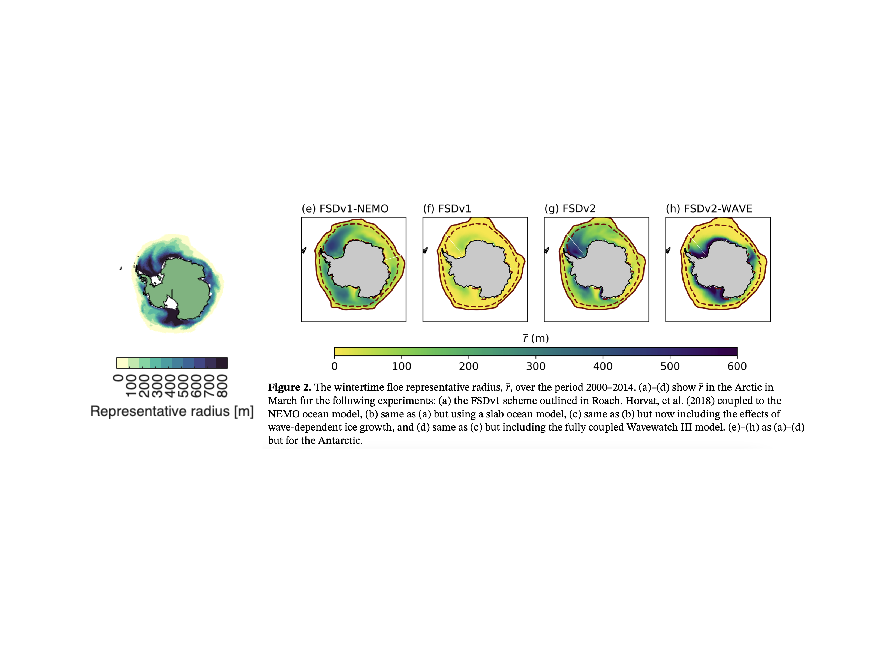

clear filename
figure;
sector = "SH";
% Reproduce Currently winter == AUGUST
%filename.sep = strcat('cases/',case_name,'/history/iceh.2005-08.nc');
filename.sep = '/Users/noahday/Maths1/spectrum_fixed/history/iceh.2005-09.nc';
fsdrad_sep = data_format_sector(filename.sep,"fsdrad",sector);
% Apply 1% Mask
SIC = 0.01;
afsd = data_format_sector(filename.sep,"afsd",sector);
%temp = data_format_sector(filename.sep,"aice",sector);
temp(:,:) = fsd_converter(filename.sep,"afsd","aice",afsd,"SA");
ice_mask(:,:) = temp > 0.01;
temp(~ice_mask(:,:)) = NaN;
aice(:,:) = temp;
fsdrad_sep(~ice_mask(:,:)) = NaN;

max_rad = 3000;
subplot(1,5,1)
[w, a, ~] = map_plot(fsdrad_sep,"fsdrad","SHplain"); 
cmocean('deep',10)
a.Location = 'southoutside';
a.Label.String = 'Representative radius [m]';
%a.Ticks = [0,200,400,600];
a.Ticks = [0,100,200,300,400,500,600,700,800];
caxis([0,850]);

subplot(1,5,[2,5])
imshow(imread("observations/roach_2019/fig2.png"))

clear temp w a output_data fsdrad_march fsdrad_sep aice icemask max_rad filename

### Model output: CICE experiments with varying floe and wave physics (https://zenodo.org/record/3463580#.Ysyymi8Rojc)

#### Comparison of WW3 significant wave heights

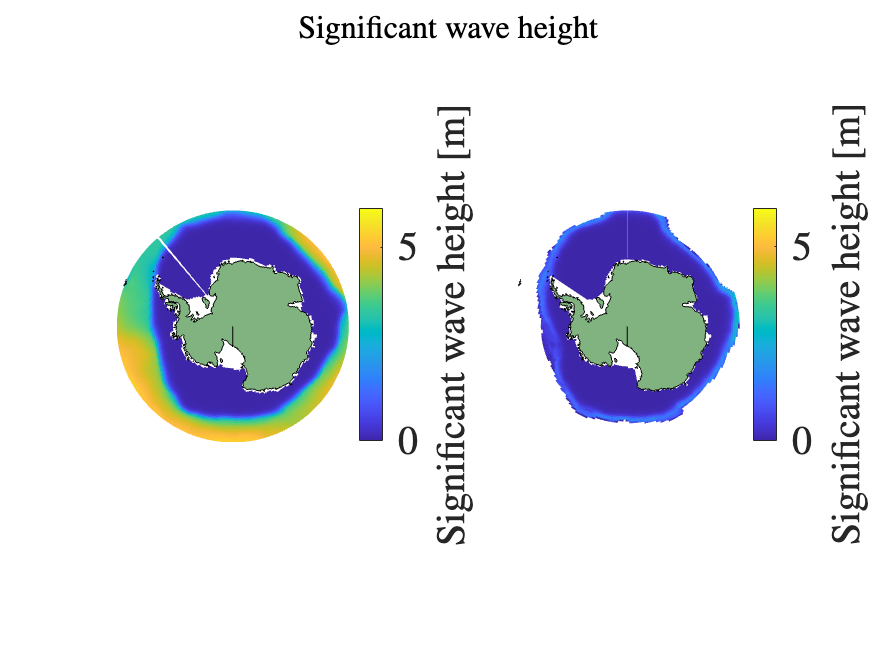

filename_roach19_swh = "/Volumes/NoahDay5TB/roach_2019/ww3_sigheight_FSDv2-WAVE_LR_2000-2014.nc";
lat_roach19 = ncread(filename_roach19_swh,"latitude");lon_roach19 = ncread(filename_roach19_swh,"longitude");
swh_t = ncread(filename_roach19_swh,"hs");% time is in months take the last september
swh_roach19(:,:) = swh_t(:,:,177); 
puny   = 1.0e-11;
idx = swh_roach19 < puny;
swh_roach19(idx) = NaN;
%filename = strcat('cases/',case_name,'/history/iceh.2005-09.nc');
filename = '/Users/noahday/maths1/spectrum_fixed/history/iceh.2005-09.nc';
swh = data_format_sector(filename,"wave_sig_ht","SH");
idx = swh < puny;
swh(idx) = NaN;


figure;   
subplot(1,2,1)
title("Roach et al. (2019)")
w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat_roach19),double(lon_roach19),swh_roach19);
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
                a = colorbar;
                caxis([0,6])
                %cmocean('balance,10')
                a.Label.String = "Significant wave height [m]";
                a.Label.Interpreter = "latex";
subplot(1,2,2)
title("ND: waves")
w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat),double(lon),swh);
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
                a = colorbar;
                caxis([0,6])
                a.Label.String = "Significant wave height [m]";
                a.Label.Interpreter = "latex";
                %cmocean('balance,10')
sgtitle('Significant wave height','FontSize',20) 

## Functions

function [data_out,afsd,aice,dafsd] = integrate_afsd_hemi(lat,floe_binwidth,afsd)

    [len,wid] = size(lat);
    % Calculate aice
    for i = 1:len
        for j = 1:wid
            temp(:) = afsd(i,j,:);
            %disp(floe_binwidth')
            aice(i,j) = sum(temp.*floe_binwidth');
            clear temp
        end
    end
    %clear len wid
    
    % Define ice masks
    SIC = 0.01; % 1% ice mask
    ice_mask = aice > SIC;
    SH_mask = lat < 0;
    
    % Apply ice masks
    
    %for i = 1:length(floe_binwidth)
    %    temp(:,:) = afsd(:,:,i).*SH_mask;
    %    temp(~ice_mask) = NaN;
    %    afsd(:,:,i) = temp;
    %    temp2 = temp(ice_mask); % sea ice
    %    idx = isnan(temp2);
    %    fsd_int(i) = mean(temp(ice_mask));
    %    dafsd = temp2(~idx);
    %    if numel(idx) == numel(temp2)
    %        fsd_int(i) = 0;
    %    else
    %        fsd_int(i) = mean(temp2(~idx));
    %    end
        
    %    clear temp temp2
    %end
    afsd_tally = [];
    for i = 1:len
        for j = 1:wid
            if aice(i,j) > eps
                temp(:) = afsd(i,j,:);;
                afsd_tally = [afsd_tally; temp];
                clear temp
            end
        end
    end
    fsd_int = mean(afsd_tally);
    data_out = fsd_int;
end






function [data_out] = dfsdrad(lat,NFSD,floe_binwidth,afsd)

    [len,wid] = size(lat);
    % Calculate aice
    for i = 1:len
        for j = 1:wid
            temp(:) = afsd(i,j,:);
            fsdrad(i,j) = sum(temp.*floe_binwidth.*NFSD');
            clear temp
        end
    end
    clear len wid
    
    % Define ice masks
    SIC = eps; % 1% ice mask
    ice_mask = fsdrad > SIC;
    SH_mask = lat < 0;
    
    % Apply ice masks
    temp(:,:) = fsdrad(:,:).*SH_mask;
    %temp(~ice_mask) = NaN;


    data_out = temp;
end